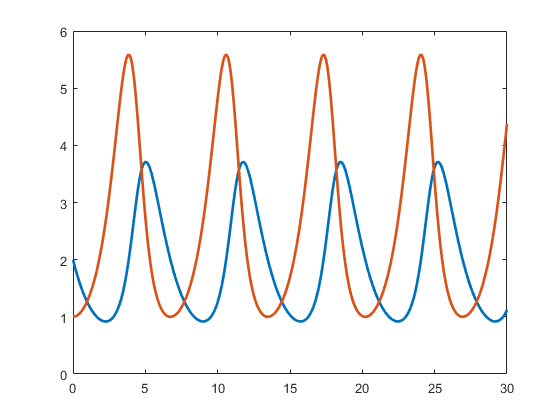

clc,clear,close all
a = 1.2; b = 0.6; c = 0.8; d = 0.3;
dx = @(t,x) [-c*x(1)+d*x(1)*x(2);
    a*x(2)-b*x(1)*x(2)];
x0 = [2;1];
h = 0.1;
t = [0,30];


x = Runge_Kutta(dx,t,h,x0);
plot(t(1):h:t(2),x(1,:),t(1):h:t(2),x(2,:),"LineWidth",2)